lstm有两种预测方式，区别如图

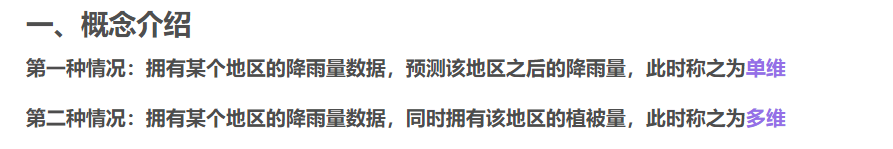

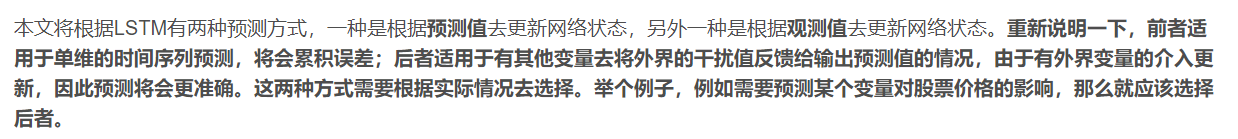

方法一

1、定义训练集即数据预处理

clc,clear;
data=[1 3 5 2 4 3 5 4 3 1 4 6 5 4 6 6 3 6 8 6 7 8 9 9];
% data=data(:,2)';  %不转置的话，无法训练lstm网络，显示维度不对。
dataTrain = data(1:20);    %定义训练集
dataTest = data(21:24);    %该数据是用来在最后与预测值进行对比的
%% 数据预处理
mu = mean(dataTrain);    %求均值 
sig = std(dataTrain);      %求均差 
dataTrainStandardized = (dataTrain - mu) / sig;  

2、交替时间步

%% 输入的每个时间步，LSTM网络学习预测下一个时间步，这里交错一个时间步效果最好。
XTrain = dataTrainStandardized(1:end-1);  
YTrain = dataTrainStandardized(2:end); 

3、定义LSTM网络架构并训练

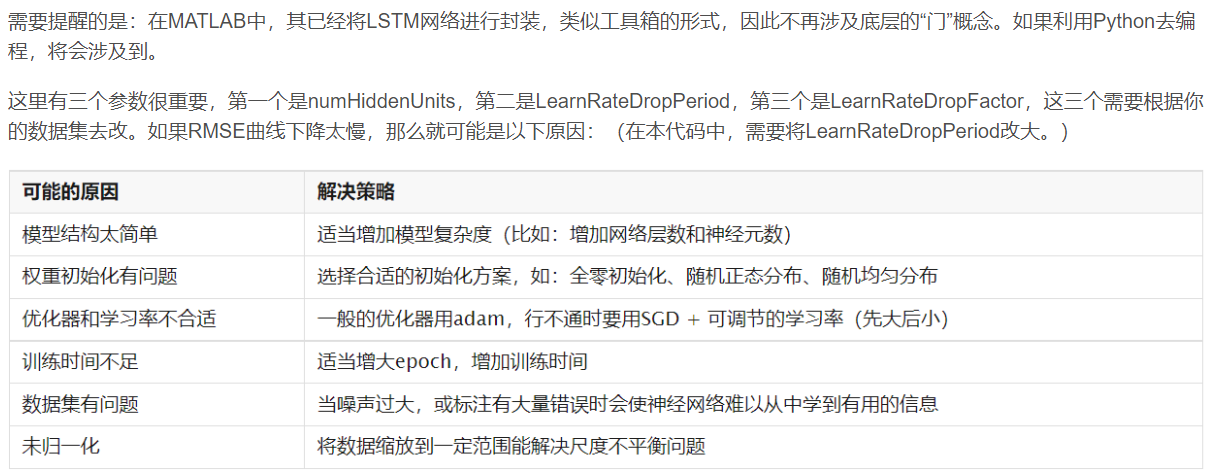

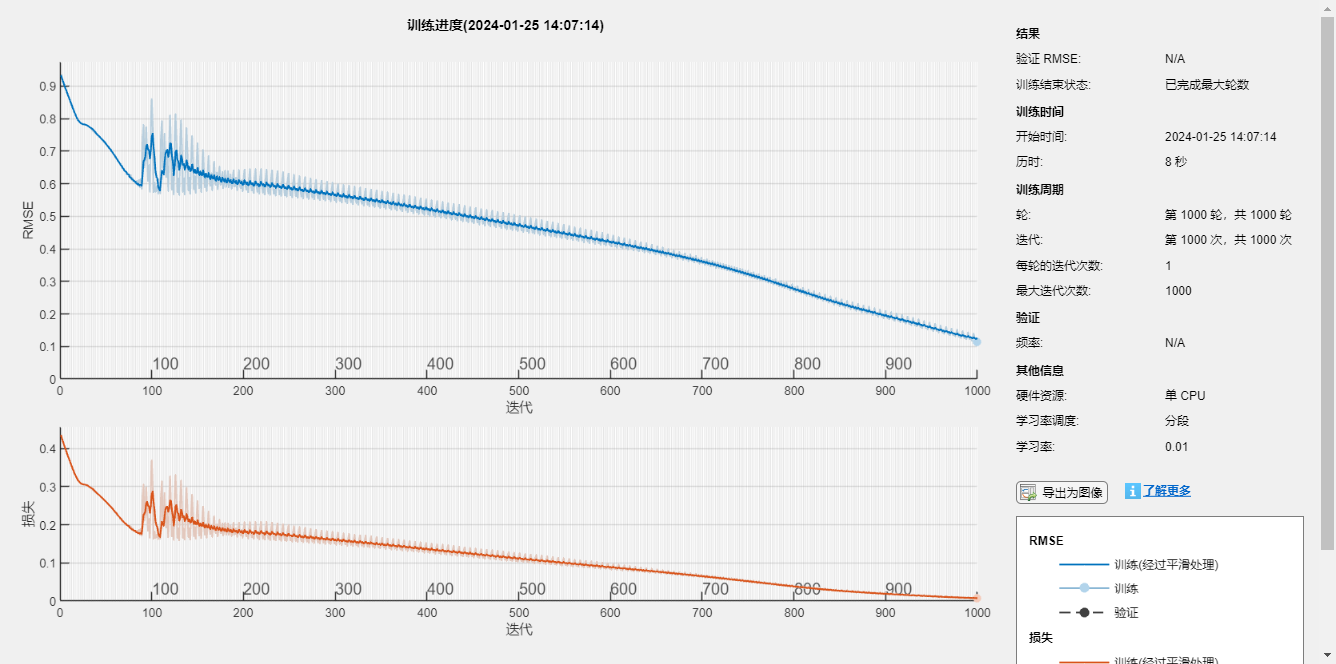


%% 一维特征lstm网络训练
numFeatures = 1;   %特征为一维
numResponses = 1;  %输出也是一维
numHiddenUnits = 5;   %创建LSTM回归网络，指定LSTM层的隐含单元个数5。可调
 
layers = [ ...
    sequenceInputLayer(numFeatures)    %输入层
    lstmLayer(numHiddenUnits)  % lstm层，如果是构建多层的LSTM模型，可以修改。
    fullyConnectedLayer(numResponses)    %为全连接层,是输出的维数。
    regressionLayer];      %其计算回归问题的半均方误差模块 。即说明这不是在进行分类问题。
 
%指定训练选项，求解器设置为adam， 1000轮训练。
%梯度阈值设置为 1。指定初始学习率 0.01，在 125 轮训练后通过乘以因子 0.2 来降低学习率。
options = trainingOptions('adam', ...
    'MaxEpochs',1000, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.01, ...      
    'LearnRateSchedule','piecewise', ...%每当经过一定数量的时期时，学习率就会乘以一个系数。
    'LearnRateDropPeriod',1200, ...      %乘法之间的纪元数由" LearnRateDropPeriod"控制。可调
    'LearnRateDropFactor',0.15, ...      %乘法因子由参“ LearnRateDropFactor”控制，可调
    'Verbose',0,  ...  %如果将其设置为true，则有关训练进度的信息将被打印到命令窗口中。默认值为true。
    'Plots','training-progress');    %构建曲线图 将'training-progress'替换为none
net = trainNetwork(XTrain,YTrain,layers,options);

4、初始化网络状态

net = predictAndUpdateState(net,XTrain);  %将新的XTrain数据用在网络上进行初始化网络状态
[net,YPred] = predictAndUpdateState(net,YTrain(end));  %用训练的最后一步来进行预测第一个预测值，给定一个初始值。这是用预测值更新网络状态特有的。

5、利用LSTM网络进行单步预测

%% 进行用于验证神经网络的数据预测（用预测值更新网络状态）
for i = 2:9  %从第二步开始，这里进行4次单步预测(4为用于验证的预测值，5为往后预测的值。一共9个）
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');  %predictAndUpdateState函数是一次预测一个值并更新网络状态
end

6、将预测结果与实际数据对比

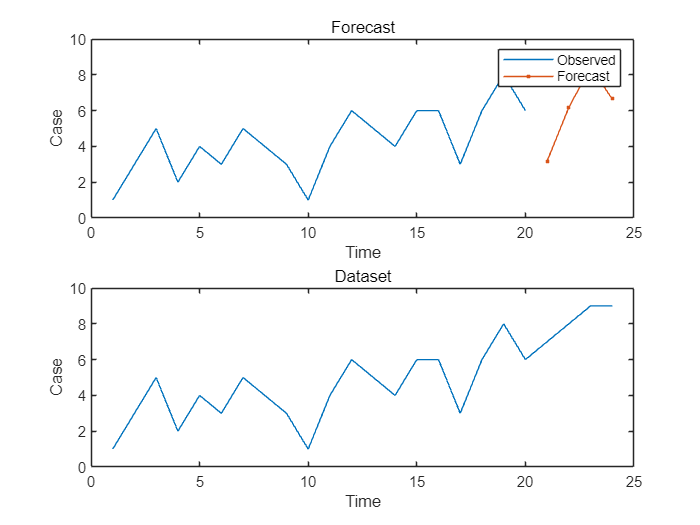

%% 验证神经网络
YPred = sig*YPred + mu;      %使用先前计算的参数对预测去标准化。
rmse = sqrt(mean((YPred(1:4)-dataTest).^2)) ;     %计算均方根误差 (RMSE)。
subplot(2,1,1)
plot(dataTrain(1:end))   %先画出前面20个数据，是训练数据。
hold on
idx = 21:(20+4);   %为横坐标
plot(idx,YPred(1:4),'.-')  %显示预测值
hold off
xlabel("Time")
ylabel("Case")
title("Forecast")
legend(["Observed" "Forecast"])
subplot(2,1,2)
plot(data)
xlabel("Time")
ylabel("Case")
title("Dataset")

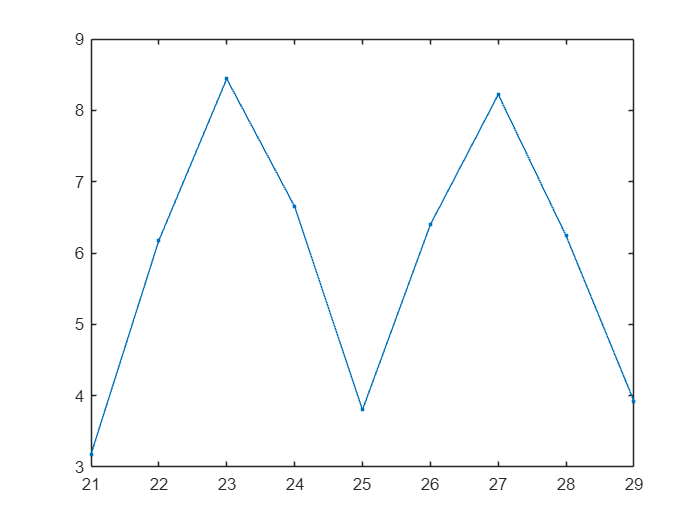

%% 继续往后预测2023年的数据
figure(2)
idx = 21:(20+9);   %为横坐标
plot(idx,YPred(1:9),'.-')  %显示预测值
hold off

7、重置网络状态（如果要更改预测个数需要刷新网络状态）

net = resetState(net);  

方法二：

目前没多维影响的数据，需要可查看[参考](https://blog.csdn.net/m0_56146217/article/details/123577068)